# Binary Image Prcessing

An idea occured to me about processing images of fractures. 

**Why don't I utilize Matlab's Image Processing Toolbox for my work?**

Here I will try a few different things to see if I can do produce good results without much fuss without MSHFF.

- Generate a skelaton image of the fractures

- Generate a Euclidian distance given the skelaton on an image

-     This will provide some means about measuring the fracture aperture.

- Find a way to calculate the orientation of the fractures

-     This will provide a statistical means of measuring the fracture orientation

## Starting with generating a synthetic fracture image

Create a synthetic image of a fracture that is represnted by an ellipse

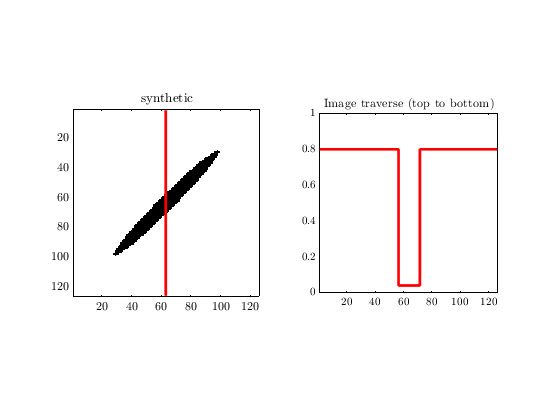

clc; close all; clearvars;

x0 = 0;
y0 = 0;
eaxes       = [100 10]; % ellipse/ellipsoid axes in the order [x y z]
radiuses    = eaxes /2;
maxradius   = max(radiuses);
m = 1.25;
X = -m*maxradius:m*maxradius; 
Y = -m*maxradius:m*maxradius;
[x, y] = meshgrid(X,Y);

% create two rows with n columns where each column is the [x y]' position vector of each pixel 
xx = [x(:)'-x0; y(:)'-y0];

B = diag((1./radiuses).^2);
theta = pi/4;

% rotation matrix
R = [cos(theta), -sin(theta);
     sin(theta),  cos(theta)];

img = dot(xx,R'*B*R*xx) < 1; 

img = reshape(img,size(x));

% fractures are usually darker features
img = imcomplement(img);

% since gray values of air isn't 0, I'll choose a the value of .8 for the
% matrix and 10/256 for air
img = double(img) * .8; 
% I'm having to use double because imnoise clips values above 1
img(img == 0) = 10/256;

figure
show(img,'synthetic'); colormap('gray');

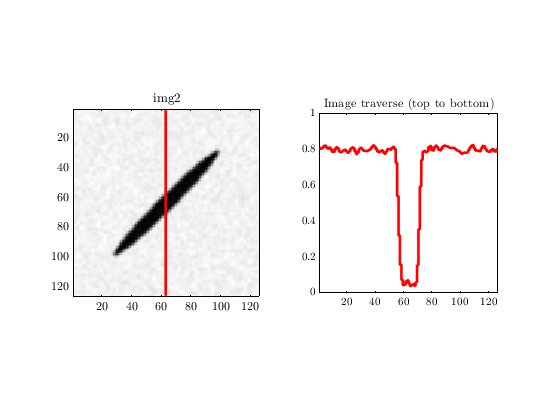

% adding some noise to the i
img2 = imnoise(img,'gaussian',0,0.002);

% blurring the image slightly
img2 = imgaussfilt(img2,1);
figure
show(img2,'img2'); colormap('gray');

## Writing the `realistic` image to file

I will write the realistic image to a file, load it into `Blob3D`, perform fracture calculations, and bring back the restuls for inspection. For this to work, I have to generate a 3d image. See blow

img23d = repmat(img2,[1 1 3]);

doWrite = 1;
imgdir = fullfile('output','2D','synth images','ellipse');

if doWrite
    writeImageSeq(img23d,imgdir,'ellipse','tif');
end

## Deblurring the image

Since I generated the synthetic image, I used a box filter with filter size of 5. Here I will use a rather different approach. But in an actual dataset, I will be able to get a better estimate of the psf from Blob3D. 

% estimatedPSF = fspecial('gaussian',5,1);
% imagesc(estimatedPSF); colorbar
% 
% [imgDeblurred,restoredPSF] = deconvblind(img,estimatedPSF);
% imshow(imgDeblurred)
% 
% figure
% values = improfile(imgDeblurred,[50 50], [1 100]);
% l = stairs_centered(1:100,values,1,'r');
% l.LineWidth = 2;
% title('Image traverse (top to bottom)')

I'm not sure This resulted in what I wanted, so I will ignore it for now. 

## Binarizing the image

To get the desired result from `bwskel`, we must genearte the image complement for the function `bwskel` to generate an output with the skelaton passing through the middle of the fracture, so we generate the complement, then binarize it and inspect it.

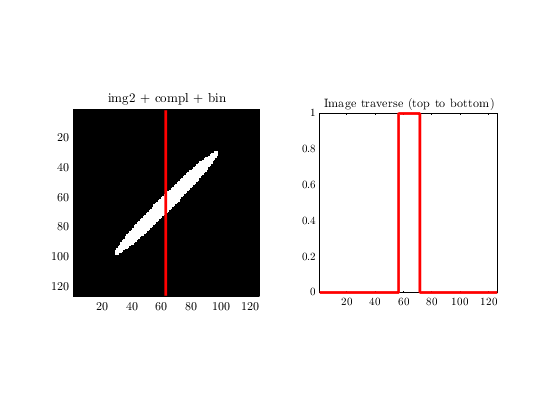

img2Complement  = imcomplement(img2);
img2BW          = imbinarize(img2Complement); 
show(img2BW,'img2 + compl + bin');

## Generating the image skelaton

The following shows the skelaton of the image 

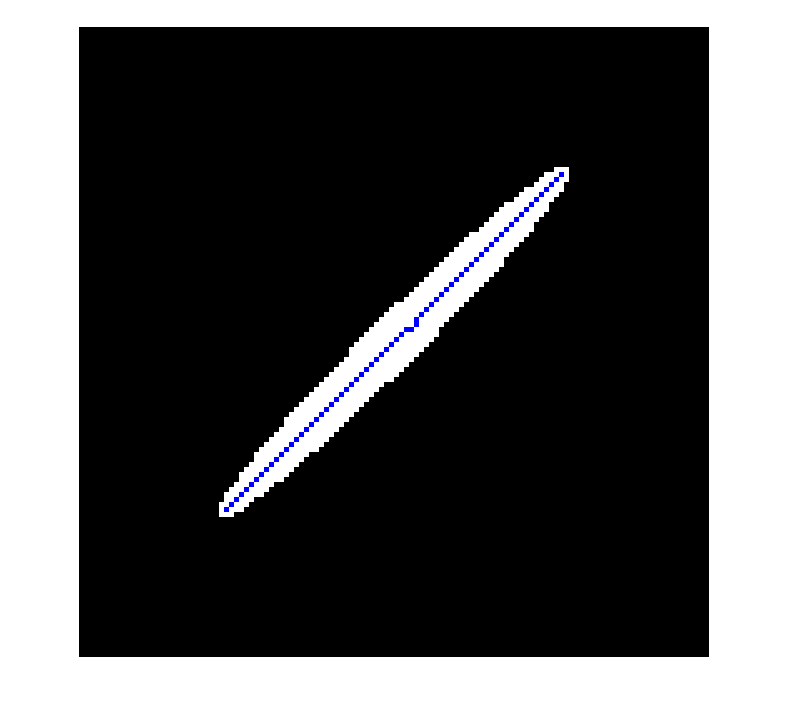

img2skl = bwskel(img2BW);
figure 
imshow(labeloverlay(double(img2BW),img2skl,'Transparency',0),'InitialMagnification',500);

## Generating the distance function

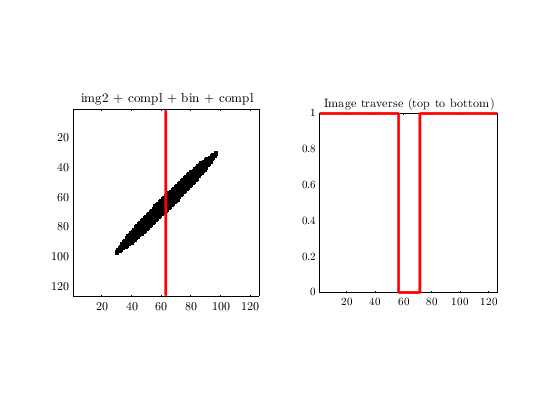

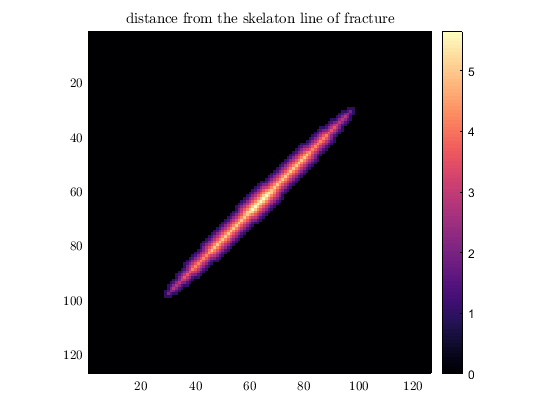

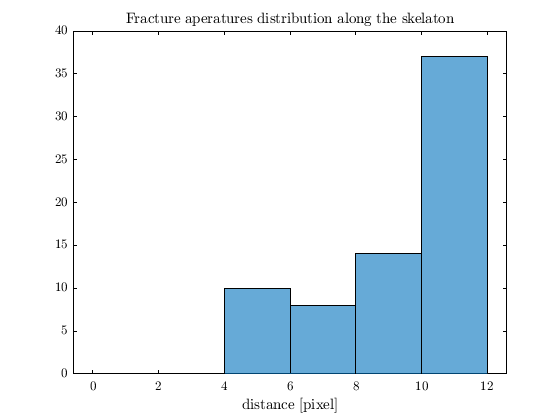

 File dos not exist


img2BWComp = imcomplement(img2BW); 
figure;
show(img2BWComp,'img2 + compl + bin + compl');
img2dist = bwdist(img2BWComp);
figure; 
imagesc(img2dist); colorbar; axis image
title('distance from the skelaton line of fracture')
figure; 
histogram(img2dist(img2skl)*2,8,'BinEdges',0:2:12);
title('Fracture aperatures distribution along the skelaton')
xlabel('distance [pixel]')


meanApr = mean(img2dist(img2skl))*2

meanApr = single
8.7636

## Blob3D result comparison

We loaded `img2rd` into `Blob3D` with the following parameters:

- Inter-pixel Spacing in mm = 0.01

- Inter-slice Spacing in mm = 0.01

We then measured the fracture apertue with the following parameters:

- PSF = 3.55

- Thin feature CT value = 10

blob3ddata = readtable('output\results\blob3d\ellipse\ellipse-fracture measurement.dat');

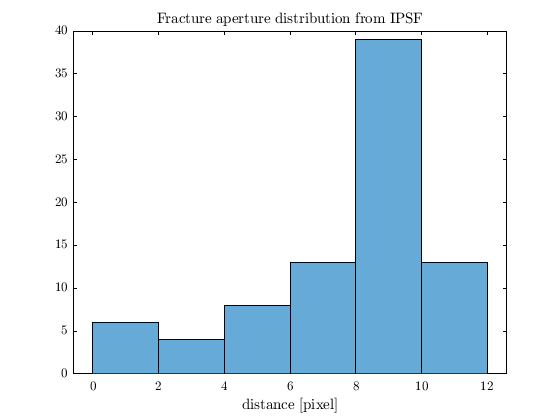

histogram(blob3ddata.ApparentWidth_vox_,8,'BinEdges',0:2:12)
title('Fracture aperture distribution from IPSF')
xlabel('distance [pixel]')

meanAprB3D = mean(blob3ddata.ApparentWidth_vox_)

meanAprB3D = 7.7152

## Actual sample: 7A_fractured

sevenAFolder = fullfile('..','..','data','Bland','7A_fractured','8bitJPG');
sevenA.original = loadImageSeq(sevenAFolder,'jpg');

loadImageSeq: file extension are properly formatted as jpg
loadImageSeq: loading image sequence from: ..\..\data\Bland\7A_fractured\8bitJPG
loadImageSeq:....................................................................................................100%
loadImageSeq completed in 15.997328.3 seconds


## Analyzing 7A_fractured

sevenA.processed.compl = imcomplement(sevenA.original.image);

## inspecting the complement

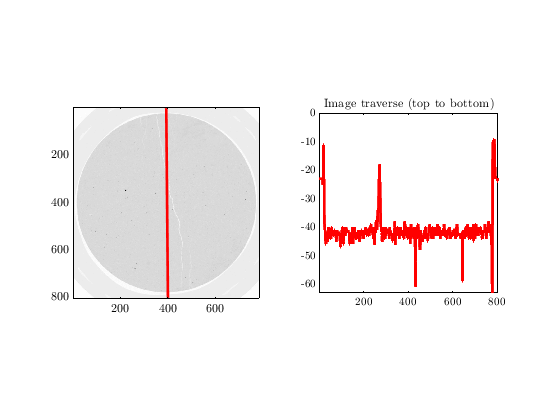

show(sevenA.processed.compl(:,:,500)); 

## inspecting the binary image

## Inspect a slice

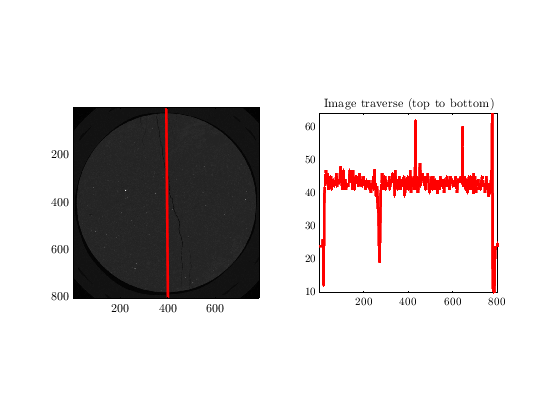

show(sevenA.origianl.image(:,:,500))

## Helper functions

function fig =show(img,varargin)
if nargin < 2
    thetitle = '';
else
    thetitle = varargin{1};
end

figure
subplot 121
imagesc(img);
if ~strcmp(thetitle,'')
    title(thetitle)
end
colormap('gray');
%colorbar("peer",gca,'westoutside');
axis('on','image'); 
hold on;
x = [fix(size(img,2)/2) fix(size(img,1)/2)];
y = [1 size(img,1)];
plot(x, y,'r','DisplayName','Traverse','LineWidth',2);
ax1 = gca; 

subplot 122
values = improfile(img,x,y);
l = stairs_centered(1:y(2),values,1,'r');
l.LineWidth = 2;
ax2 = gca;
%ax2.YLim = [floor(min(values)) ceil(max(values))];
ax2.XLim = ax1.YLim;
ax2.OuterPosition(3:4) = ax1.OuterPosition(3:4);
title('Image traverse (top to bottom)')
axis square

fig = gcf; 
end